# ***Feedforward Neural Network for Estimation of Gain Coefficients in Fiber Optics Amplifier***

## Ghani Amri Rabbani, Ary Syahriar, Dwi Astharini

This script is a supmlementary code of both standardized and non-standartdized version of FNN that included in the research paper for comprehensive analysis with BONN.

**Instructions for Downloading and Running the Script**

- Download raw datasets of Fiber Optics Amplifier doping materials from SOTON page [http://dx.doi.org/10.5258/SOTON/D1062](http://dx.doi.org/10.5258/SOTON/D1062) and [http://dx.doi.org/10.5258/SOTON/D2402](http://dx.doi.org/10.5258/SOTON/D2402) 

- After downloading all the files including this one, unzip the file to a folder, do not modify the folder structure.

- Navigate to the folder with "FNN_Optical_Fiber.mlx".

- Open and run "FNN_Optical_Fiber.mlx".

- The matlab script should run without any modification, if there is an issue it's likely due to typos or the testing and training data not being in the expected place.

- If required to modify the script, follow the comprehensive step-by-step in README file.

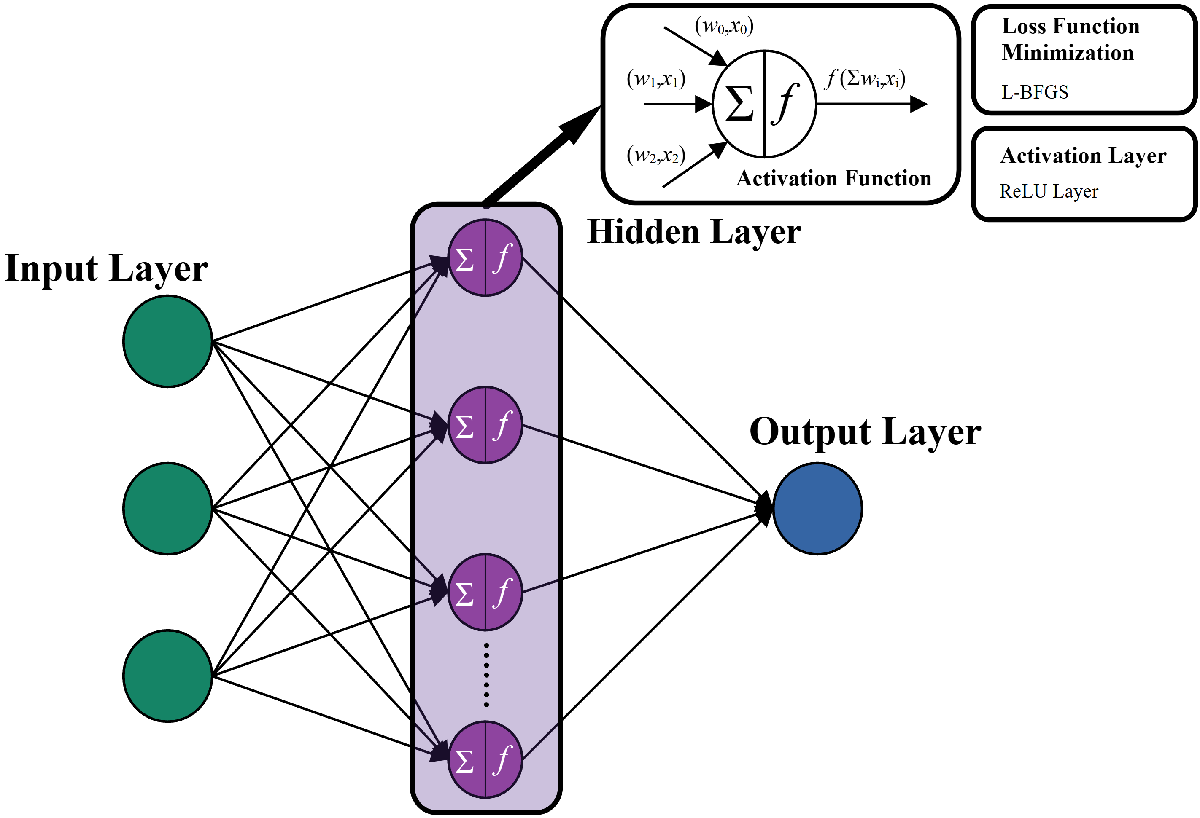

Load all of dataset. For specified coefficient, try to comment and uncomment text below. For example, if you want to perform a training at P = 0, then uncomment the code.

clear all
load Doping Materials Datasets\Preprocessed Dataset\Absorption_Emission_P0.mat
%load Doping Materials Datasets\Preprocessed Dataset\Absorption_Emission_P01.mat
%load Doping Materials Datasets\Preprocessed Dataset\Absorption_Emission_P02.mat
%load Doping Materials Datasets\Preprocessed Dataset\Absorption_Emission_P03.mat
%load Doping Materials Datasets\Preprocessed Dataset\Absorption_Emission_P04.mat
%load Doping Materials Datasets\Preprocessed Dataset\Absorption_Emission_P05.mat
%load Doping Materials Datasets\Preprocessed Dataset\Absorption_Emission_P06.mat
%load Doping Materials Datasets\Preprocessed Dataset\Absorption_Emission_P07.mat
%load Doping Materials Datasets\Preprocessed Dataset\Absorption_Emission_P08.mat
%load Doping Materials Datasets\Preprocessed Dataset\Absorption_Emission_P09.mat
%load Doping Materials Datasets\Preprocessed Dataset\Absorption_Emission_P1.mat

Split the data for Training (80%) and for Testing/Validation (20%)

rng('default')
c = cvpartition(size(Tbl,1),'Holdout',0.2);
trainingIndices = training(c);
validationIndices = test(c);
TblTrain = Tbl(trainingIndices,:);
TblValidation = Tbl(validationIndices,:);

Began neural network training

Mdl_FNN = fitrnet(TblTrain, 'Gain Coeff p0', ...
    'Standardize', 1, ... % If you want to utilized non-standardized FNN training, place a command (%) to convert into a comment
    'ValidationData', TblValidation, ...
    'Verbose', 1);

|==========================================================================================|
| Iteration  | Train Loss | Gradient   | Step       | Iteration  | Validation | Validation |
|            |            |            |            | Time (sec) | Loss       | Checks     |
|==========================================================================================|
|           1|    0.404939|    0.543348|    0.424800|    0.016941|    0.390526|           0|
|           2|    0.319687|    0.199170|    0.123201|    0.010966|    0.387980|           0|
|           3|    0.198046|    0.206565|    0.261222|    0.006339|    0.278475|           0|
|           4|    0.029632|    0.078490|    0.740004|    0.004446|    0.054106|           0|
|           5|    0.022875|    0.103175|    0.158417|    0.008867|    0.033757|           0|
|           6|    0.019103|    0.050707|    0.030987|    0.001548|    0.030956|           0|
|           7|    0.015979|    0.039043|    0.080017|    0.000550|    

Summerize training results

Train.iteration = Mdl_FNN.TrainingHistory.Iteration;
Train.trainLosses = Mdl_FNN.TrainingHistory.TrainingLoss;
Train.valLosses = Mdl_FNN.TrainingHistory.ValidationLoss;
Train.time = Mdl_FNN.TrainingHistory.Time;
TotalTime = sum(Train.time,"all");
disp(TotalTime) % in seconds

    0.0764



Plotting Mean Square Error from training

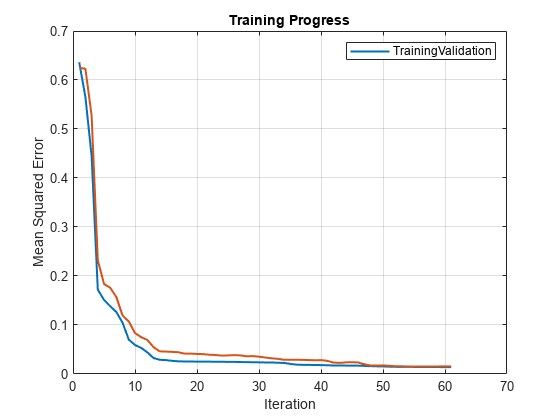

figure
plot(Train.iteration,sqrt(Train.trainLosses),Train.iteration,sqrt(Train.valLosses),'LineWidth',1.5)
legend(['Training','Validation'])
xlabel('Iteration')
ylabel('Mean Squared Error')
title('Training Progress')
grid on

Plotting Mean Square Error from training

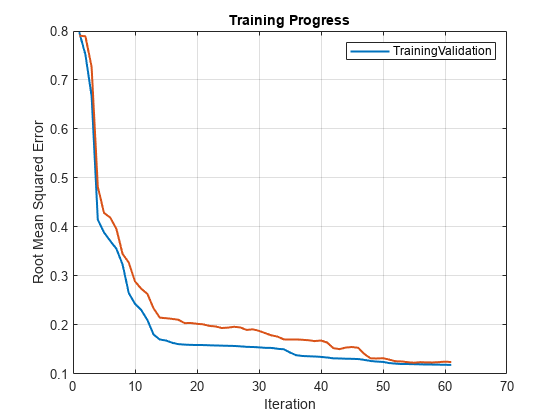

figure
plot(Train.iteration,sqrt(sqrt(Train.trainLosses)),Train.iteration,sqrt(sqrt(Train.valLosses)),'LineWidth',1.5)
legend(['Training','Validation'])
xlabel('Iteration')
ylabel('Root Mean Squared Error')
title('Training Progress')
grid on

Calculate the prediction error and prediction RMSE

testPredictions = predict(Mdl_FNN,X);
Error_test = testPredictions - GainCoefficient_p0;
RMSE = sqrt(mean((Error_test).^2))*100;

Plot the results

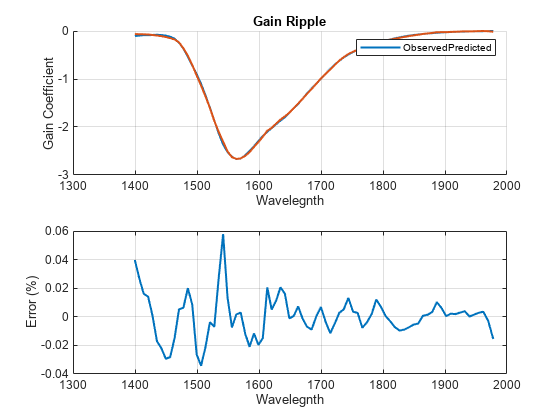

figure
subplot(2,1,1)
hold all
grid on
plot(GainCoefficient_Wave,GainCoefficient_p0,'LineWidth',1.5)
plot(GainCoefficient_Wave,testPredictions,'LineWidth',1.5)
legend(['Observed' 'Predicted'])
xlabel('Wavelegnth')
ylabel('Gain Coefficient')
title('Gain Ripple')
subplot(2,1,2)
plot(GainCoefficient_Wave,GainCoefficient_p0,'LineWidth',1.5)
plot(GainCoefficient_Wave,Error_test,'LineWidth',1.5)
xlabel('Wavelegnth')
ylabel('Error (%)')
grid on

## Copyright Notice

This code is the original works by Ghani Amri Rabbani, Ary Syahriar, Dwi Astharini under MIT 2.0 licence. All right reserved.

## Reference

[1] Chen, Jung, Alam, Richardson, Sidharthan, Ho, Yoo, & Daniel. (2020, March 18). *Dataset for: Ultra-short wavelength operation of thulium doped fiber amplifiers and lasers*. ePrints Soton. [https://eprints.soton.ac.uk/438624/](https://eprints.soton.ac.uk/438624/) 

[2] Zhai, Halder, & Sahu. (2023, March 1). *Data in support of the conference paper “erbium-doped fiber amplifier with extended L-band gain to 1625 nm.”* ePrints Soton. [https://eprints.soton.ac.uk/475237/](https://eprints.soton.ac.uk/475237/) 